# Linear Control Design II - Group Work Problem Module 7 

                Roberto Galeazzi (2015), Hjalte Bested Møller (2017)

		        Department of Electrical Engineering 

                            Technical University of Denmark 

                                        August, 2017

## Description	

A system with three interconnected tanks is shown in Fig.1. The tanks have the cross sectional areas $A_1$, $A_2$ and $A_3$. The input flows are proportional to the input voltages, that is


$$q_a = k u_1$$



$$q_b = k u_2$$


The flows follow the square root law and since the pressures in the bottoms of the tanks are proportional to the level, one has 


$$q_1 = c_1 \sqrt{x_1-x_2}$$



$$q_2 = c_2 \sqrt{x3-x2}$$



$$q_0 = c_0 \sqrt{x_2}$$


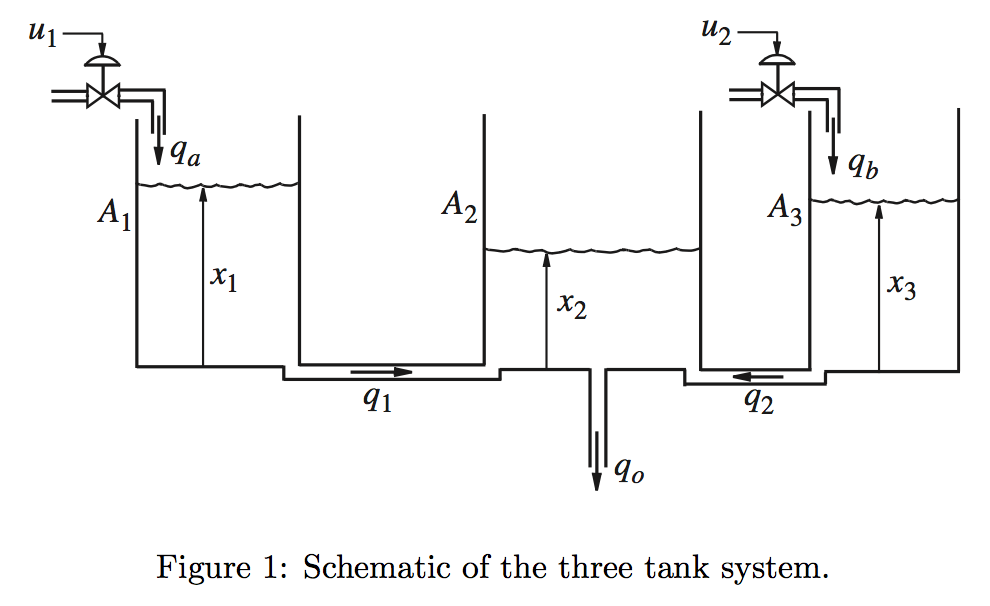				

**Problem 1**  Derive the set of equations describing the system and formulate the nonlinear state model with the two inputs $u_1$ and $u_2$, and the output = $q_0$. 

% Your solution goes here:
clear
syms x1 x2 x3 c0 c1 c2 q0 q1 q2 k u1 u2 A1 A2 A3
qa=k*u1;qb=k*u2;q1=c1*sqrt(x1-x2);q2=c2*sqrt(x3-x2);q0=c0*sqrt(x2);
f1 = (qa-q1)/A1;
f2 = (q1+q2-q0)/A2;
f3 = (qb-q2)/A3;
x = [x1;x2;x3];
u = [u1;u2];
f(x1,x2,x3,u1,u2) = [f1;f2;f3], g(x1,x2,x3,u1,u2) = q0

$$f(x1, x2, x3, u1, u2) = \left(\begin{array}{c} \frac{k\,u_{1}-c_{1}\,\sqrt{x_{1}-x_{2}}}{A_{1}}\\ \frac{c_{1}\,\sqrt{x_{1}-x_{2}}-c_{0}\,\sqrt{x_{2}}+c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{2}}\\ \frac{k\,u_{2}-c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{3}} \end{array}\right)$$

$$g(x1, x2, x3, u1, u2) = c_{0}\,\sqrt{x_{2}}$$

**Problem 2**  Find the stationary point under the assumption that the inputs are $u_1 = u_{10}$ and $u_2 = u_{20}$. 					

% Your solution goes here:


$$\dot{x_1 } =0\Rightarrow \frac{k{\text{ }u}_{10} -c_1 \text{ }\sqrt{x_{10} -x_{20} }}{A_1 }=0\Rightarrow k\text{ }u_{10} =c_1 \sqrt{x_{10} -x_{20} }\Rightarrow {\left(\frac{k}{c_1 }u_{10} \right)}^2 =x_{10} -x_{20}$$



$$\dot{x_3 } =0\Rightarrow {k\text{ }u}_{20} =c_2 \sqrt{x_{30} -x_{20} }$$



$$\dot{x_2 } =0\Rightarrow c_1 \sqrt{x_{10} -x_{20} }+c_2 \sqrt{x_{30} -x_{20} }-c_0 \sqrt{x_{20} }=0\Rightarrow c_0 \sqrt{\text{ }x_{20} }=c_1 \sqrt{x_{10} -x_{20} }+c_2 \sqrt{x_{30} -x_{20} }\Rightarrow c_0 \sqrt{x_{20} }=k\text{ }\left(u_{10} +u_{20} \right)$$



$$x_{20} =k\left(u_{10} +u_{20} \right)$$



syms x10 x20 x30 u10 u20
solVar = solve(f(x1,x2,x3,u10,u20)==[0;0;0],[x1,x2,x3]);
x1_s = solVar.x1;
x2_s = solVar.x2;
x3_s = solVar.x3;
x_stationary = [x1_s;x2_s;x3_s]

$$x\_stationary = \left(\begin{array}{c} \frac{{c_{0}}^{2}\,k^{2}\,{u_{10}}^{2}+{c_{1}}^{2}\,k^{2}\,{u_{10}}^{2}+2\,{c_{1}}^{2}\,k^{2}\,u_{10}\,u_{20}+{c_{1}}^{2}\,k^{2}\,{u_{20}}^{2}}{{c_{0}}^{2}\,{c_{1}}^{2}}\\ \frac{{\left(k\,u_{10}+k\,u_{20}\right)}^{2}}{{c_{0}}^{2}}\\ \frac{{c_{0}}^{2}\,k^{2}\,{u_{20}}^{2}+{c_{2}}^{2}\,k^{2}\,{u_{10}}^{2}+2\,{c_{2}}^{2}\,k^{2}\,u_{10}\,u_{20}+{c_{2}}^{2}\,k^{2}\,{u_{20}}^{2}}{{c_{0}}^{2}\,{c_{2}}^{2}} \end{array}\right)$$

u_stationary = [u10;u20];
g(x10,x20,x30,u10,u20)

$$ans = c_{0}\,\sqrt{x_{20}}$$

**Problem 3**  Linearize the model and derive the linear state space model

            Process equation:  $\Delta \dot{\mathbf{x}} =\mathbf{A} \Delta \mathbf{x} + \mathbf{B} \Delta \mathbf{u}$

            Output equation:    $\Delta \mathbf{y} = \mathbf{C} \Delta \mathbf{x}$

% Your solution goes here:
o = [x1  x2  x3  u1  u2];
n = [x10 x20 x30 u10 u20];

% A = [diff(f1,x1) diff(f1,x2) diff(f1,x3);...
%             diff(f2,x1) diff(f2,x2) diff(f3,x3);...
%             diff(f3,x1) diff(f3,x2) diff(f3,x3)];
% B = [diff(f1,u1) diff(f2,u1) diff(f3,u1);...
%             diff(f2,u2)  diff(f2,u2)  diff(f3,u2)];
% C = [diff(g,x1) diff(g,x2) diff(g,x3)];
% D = [diff(g,u1); diff(g,u2)];
 % A = subs(A,o,n), B = subs(B,o,n), C = subs(C,o,n), D = subs(D,o,n)
A = subs(subs(jacobian(f,x),o,n)),B = subs(jacobian(f,u),o,n),C = subs(jacobian(g,x),o,n),D = subs(jacobian(g,u),o,n)

$$A(x1, x2, x3, u1, u2) = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{2} & \sigma_{2} & 0\\ \frac{c_{1}}{2\,A_{2}\,\sqrt{x_{10}-x_{20}}} & -\frac{\frac{c_{0}}{2\,\sqrt{x_{20}}}+\frac{c_{1}}{2\,\sqrt{x_{10}-x_{20}}}+\frac{c_{2}}{2\,\sqrt{x_{30}-x_{20}}}}{A_{2}} & \frac{c_{2}}{2\,A_{2}\,\sqrt{x_{30}-x_{20}}}\\ 0 & \sigma_{1} & -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{c_{2}}{2\,A_{3}\,\sqrt{x_{30}-x_{20}}}\\ \sigma_{2}=\frac{c_{1}}{2\,A_{1}\,\sqrt{x_{10}-x_{20}}} \end{array}$$

$$B(x1, x2, x3, u1, u2) = \left(\begin{array}{cc} \frac{k}{A_{1}} & 0\\ 0 & 0\\ 0 & \frac{k}{A_{3}} \end{array}\right)$$

$$C(x1, x2, x3, u1, u2) = \left(\begin{array}{ccc} 0 & \frac{c_{0}}{2\,\sqrt{x_{20}}} & 0 \end{array}\right)$$

$$D(x1, x2, x3, u1, u2) = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

% % Define System parameters:
% A1_n = 0.7;
% A2_n = 1.2;
% A3_n = 0.7; 
% 
% k_n = .002; 
% 
% c1_n = .008; 
% c2_n = .008;
% c0_n = .02;
% 
% % Your solution goes here:
% %Stationary Point
% u10_n=5;u20_n=5;
% x10 = subs(x1_s,[u10 u20 A1 A2 A3 k c0 c1 c2],[u10_n u20_n A1_n A2_n A3_n k_n c0_n c1_n c2_n])
% x20 = subs(x2_)
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c0 = .02;
u10 = 5;
u20 = 5;
x10 = eval(x1_s);
x20 = eval(x2_s);
x30 = eval(x3_s);
y0  = eval(g(x10,x20,x30,u10,u20));

eq = '   =   '

eq = '   =   '

disp([['u10';'u20';'x10';'x20';'x30';' y0'] [eq;eq;eq;eq;eq;eq] num2str([u10;u20;x10;x20;x30;y0])])

u10   =        5
u20   =        5
x10   =   2.5625
x20   =        1
x30   =   2.5625
 y0   =     0.02


genVar  = [ x1  x2  x3  u1  u2];
statVar = [x10 x20 x30 u10 u20];
Al=eval(subs(A,[u1 u2],[u10 u20])),...
Bl=eval(subs(B,[u1 u2],[u10 u20])),...
Cl=eval(subs(C,[u1,u2],[u10 u20])),...
Dl=eval(subs(D,[u1,u2],[u10,u20])),

Al =    -0.0045714    0.0045714            0
    0.0026667    -0.013667    0.0026667
            0    0.0045714   -0.0045714


Bl =     0.0028571            0
            0            0
            0    0.0028571


Cl =             0         0.01            0


Dl =      0     0


Table 1 shows the numerical value of the system’s parameters. The working interval of the input voltages $u_1$ and $u_2$ is 0-10 volts. 

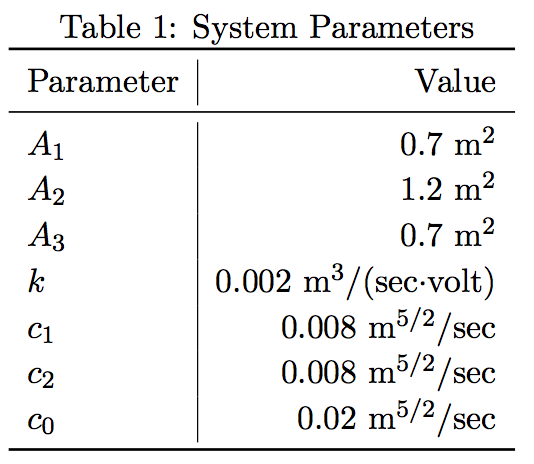

## **Problem 4 ** Set up a Simulink model of the nonlinear system and write a MatLab script to initialize the model with the needed parameter values. Remember that all input variables must be provided with an in port, and all output variables must be provided with an out port in the model.

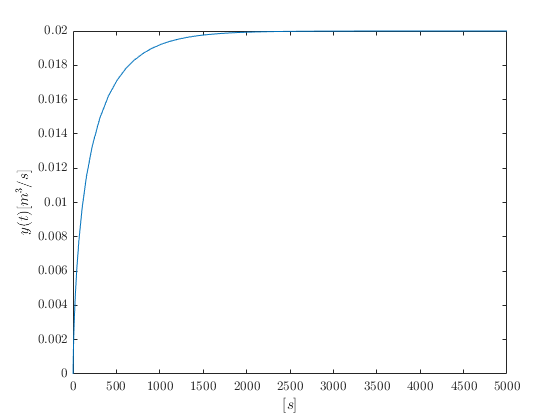

% clear, close all
% Define System parameters:
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c0 = .02;

% Your solution goes here:

x0 = [0 0 0];
t_end = 5000;
u = [u10 u20];
mdl = 'ThreeTank_NonLinear';
simSwitch = -1;
load_system(mdl)
set_param(mdl,'LoadExternalInput','off')
set_param(mdl,'LoadInitialState','off')
set_param(mdl,'SaveFinalState','on')
set_param(mdl,'SaveState','on')
set_param(mdl,'FinalStateName','xF')


% load_system(mdl)
% ds = createInputDataset(mdl);
% ds{1} = timeseries(t',u1,'Name','u1');
% ds{2} = timeseries(t',u2,'Name','u2');
% step
% set_param(mdl,'LoadExternalInput','on')
% set_param(mdl,'ExternalInput','ds')
% set_param(mdl,'LoadInitialState','off')
% set_param(mdl,'InitalState','x0')
%set_param(mdl,'StopTime','5000')
%set_param(mdl,)
[t,xout,yout]= sim(mdl,t_end);
figure
plot(t,yout),xlabel('$[s]$'),ylabel('$y(t) [m^3/s]$')

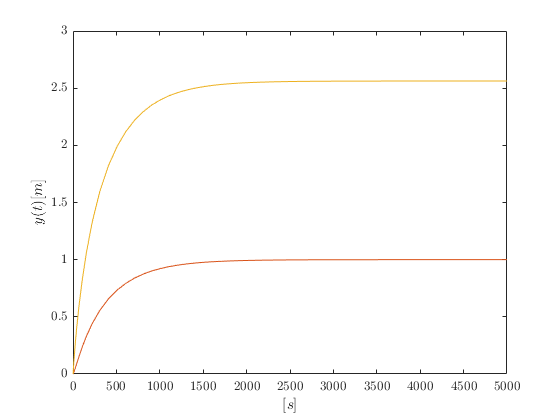

figure
plot(t,xout),xlabel('$[s]$'),ylabel('$y(t) [m]$')

**Problem 5**  Linearize the model using linmod. Set both inputs $u_1 = u_2 = 5$ volts. Simulink by default determine the numbering of the states in the model when linmod is used. It can be a little confusing when comparing Simulinks results with those obtained by manual calculations. If desired, one can determine one’s own numbering in the following way: 

- Choose an integrator in the model and do a right-button click 

- Choose Block Properties. A window opens

- Write the number desired in the Priority-field

- Close the Block Properties window 

% Your solution goes here:
simSwitch = 1;
[Aa,Bb,Cc,Dd] = linmod(mdl,xF,u)

Aa =    -0.0045714    0.0045714            0
    0.0026667    -0.013667    0.0026667
            0    0.0045714   -0.0045714


Bb =     0.0028571            0
            0            0
            0    0.0028571


Cc =             0         0.01            0


Dd =      0     0


Al,Bl,Cl,Dl

Al =    -0.0045714    0.0045714            0
    0.0026667    -0.013667    0.0026667
            0    0.0045714   -0.0045714


Bl =     0.0028571            0
            0            0
            0    0.0028571


Cl =             0         0.01            0


Dl =      0     0


**Problem 6 ** Simulate the nonlinear and linearized model for small and large variations of the system’s inputs $u_1$ and $u_2$ around their stationary values. Plot the state and output responses and try to determine which is the range of input variations where the linearized model is a good approximation of the nonlinear system. 

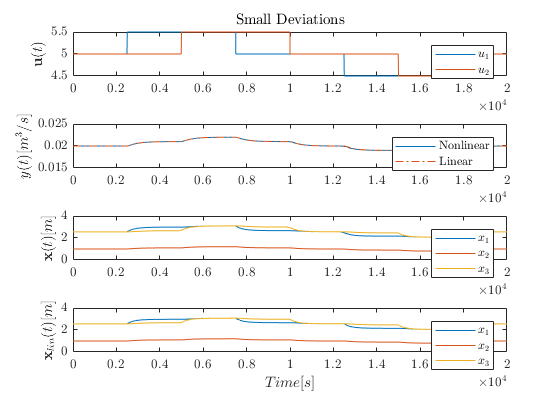

% Your solution goes here:

sys_lin = ss(Aa,Bb,Cc,Dd);
sys_lin.u = {'u1','u2'};
sys_lin.y = {'y'};
runl = 20000;
T = 0:0.1:runl;

U1 = 0;
Us = U1*ones(length(T),2);
Us(25000:75000,1) = U1+.5;
Us(50000:100000,2) = U1+.5;
Us(125000:175000,1) = U1-.5;
Us(150000:175000,2) = U1-.5;
inp = zeros(length(T),3);

[yl,tl,xl] = lsim(sys_lin,Us,T);
yl = yl+0.02;
xl(:,1) = xl(:,1)+xF(1);
xl(:,2) = xl(:,2)+xF(2);
xl(:,3) = xl(:,3)+xF(3);

Us = Us+5;

simSwitch = 1;
inp(:,1) = T';
inp(:,2:3) = Us;
x0 = xF;
[t1,x1,y1] = sim(mdl,runl,[],inp);

figure
subplot(4,1,1),plot(tl,Us),title('Small Deviations'),ylabel('$\mathbf{u}(t)$'),legend('$u_1$','$u_2$')
subplot(4,1,2),plot(t1,y1,'-',tl,yl,'-.'),ylabel('$y(t) [m^3/s]$'),legend('Nonlinear','Linear')
subplot(4,1,3),plot(t1,x1),ylabel('$\mathbf{x}(t) [m]$'),legend('$x_1$','$x_2$','$x_3$')
subplot(4,1,4),plot(tl,xl),ylabel('$\mathbf{x}_{lin}(t) [m]$'),xlabel('$Time [s]$'),legend('$x_1$','$x_2$','$x_3$')

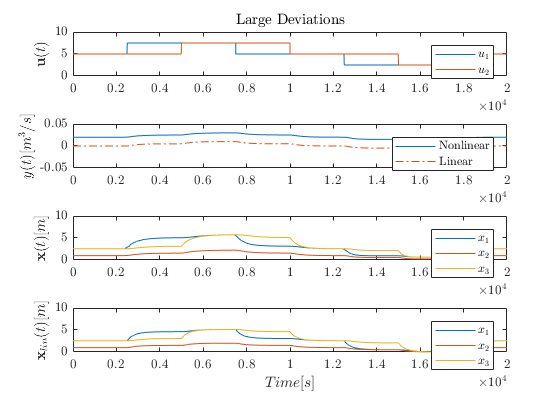

U1 = 0;
Ul = U1*ones(length(T),2);
Ul(25000:75000,1) = U1+2.5;
Ul(50000:100000,2) = U1+2.5;
Ul(125000:175000,1) = U1-2.5;
Ul(150000:175000,2) = U1-2.5;
inp = zeros(length(T),3);

[ylb,tlb,xlb] = lsim(sys_lin,Ul,T);
yl = yl+0.02;
xlb(:,1) = xlb(:,1)+xF(1);
xlb(:,2) = xlb(:,2)+xF(2);
xlb(:,3) = xlb(:,3)+xF(3);

Ul = Ul+5;
simSwitch = 1;
inp(:,1) = T';
inp(:,2:3) = Ul;
x0 = xF;
[t1b,x1b,y1b] = sim(mdl,runl,[],inp);

figure
subplot(4,1,1),plot(tlb,Ul),title('Large Deviations'),ylabel('$\mathbf{u}(t)$'),legend('$u_1$','$u_2$')
subplot(4,1,2),plot(t1b,y1b,'-',tlb,ylb,'-.'),ylabel('$y(t) [m^3/s]$'),legend('Nonlinear','Linear')
subplot(4,1,3),plot(t1b,x1b),ylabel('$\mathbf{x}(t) [m]$'),legend('$x_1$','$x_2$','$x_3$')
subplot(4,1,4),plot(tlb,xlb),ylabel('$\mathbf{x}_{lin}(t) [m]$'),xlabel('$Time [s]$'),legend('$x_1$','$x_2$','$x_3$')

**Problem 7**  Determine the transfer functions from u1 to y and from u2 to y. 

% Your solution goes here:

G = tf(sys_lin)


G =
 
  From input "u1" to output "y":
            7.619e-08 s + 3.483e-10
  -------------------------------------------
  s^3 + 0.02281 s^2 + 0.0001215 s + 1.742e-07
 
  From input "u2" to output "y":
            7.619e-08 s + 3.483e-10
  -------------------------------------------
  s^3 + 0.02281 s^2 + 0.0001215 s + 1.742e-07
 
Continuous-time transfer function.



**Problem 8**  Assess the internal and external stability of the system. 

% Your solution goes here:
po = pole(G(1,1)),zo = zero(G(1,1));

po =     -0.015832
   -0.0045714
   -0.0024062


if length(po)==length(po(real(po)<0))
    disp('The system in internally stable')
else
    disp('The system is internally unstable')
end

The system in internally stable


G = minreal(G);
po = pole(G(1,1)),zo = zero(G(1,1));

po =     -0.015832
   -0.0024062


if length(po)==length(po(real(po)<0))
        disp('The system in externally stable')
else
        disp('The system is externally unstable')

end

The system in externally stable


%%

**Problem 9**  Expand the Matlab script to compute the eigenvalues of the linearized system for input values in the entire interval 0-10 volts. Analyse the behaviour of the system eigenvalues as function of the operating point of the system. Hint: Include a for-loop which will find the stationary states by simulation over 5000 seconds for each value of $u$ (use the MATLAB function sim to simulate the system within the for-loop). Then linearize the model for each value using the final states (xFinal) as the stationary values. 


% Your solution goes here:
stp = 100;
set_param(mdl,'FinalStateName','xFinal')
xF = zeros(3,stp);
uu = zeros(stp,1);
egv = zeros(3,stp);

for ii = 1:stp
    simSwitch = -1;
    u = ii*0.1+0.1;
    uu(ii) = u;
    u = [u u]';
    sim(mdl)
    xF(:,ii) = xFinal';
    
    simSwitch = 1;
    [A,B,C,D] = linmod(mdl,xFinal,u);
    egv(:,ii) = eig(A);
end

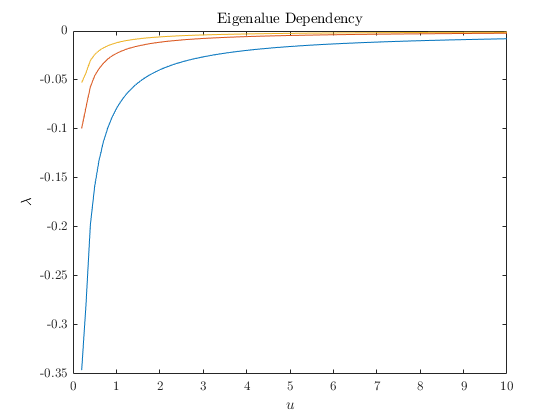

figure
plot(uu,egv),xlabel('$u$'),ylabel('$\lambda$'),title('Eigenalue Dependency')
axis([0 10 -0.35 0])

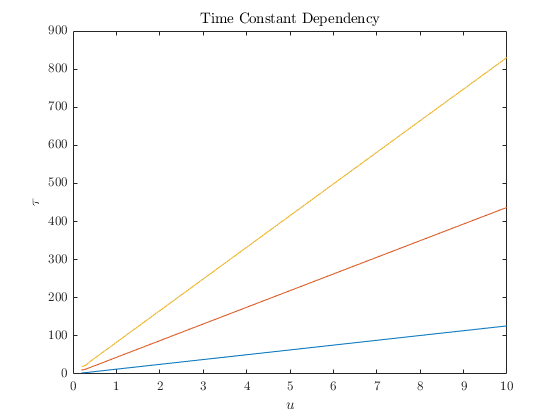

figure
plot(uu,-1./egv),xlabel('$u$'),ylabel('$\tau$'),title('Time Constant Dependency')
axis([0 10 0 900])

    
% for i = 1:2
%    simSwitch = -1;
%    uu(i,1) = i*10/stp;
%    u = [uu(i) uu(i)]'
%    sim(mdl,5000);
%    xF(:,i) = xFinal
%    
%    simSwitch = 1;
%    [Alm,Blm,Clm,Dlm] = linmod(mdl,xFinal',u)
%    egv()
% end






**Problem 10**  Choose a suitable sampling time $T_s$ and discretize the system obtained in Problem 5 using the Matlab$\mathtt{c2d}$-function. Calculate the eigenvalues of the discretized system both using the Matlab $\mathtt{eig}$-function and Frobenius theorem. Compare the obtained results. Is the discretization changing the stability properties of the system? 

% Your solution goes here:
Lambda_Aa = eig(Aa)

Lambda_Aa =     -0.015832
   -0.0045714
   -0.0024062


Ts = ceil(1/(max(abs(Lambda_Aa))*10))

Ts =      7


sys_cont = ss(Aa,Bb,Cc,Dd)


sys_cont =
 
  A = 
              x1         x2         x3
   x1  -0.004571   0.004571          0
   x2   0.002667   -0.01367   0.002667
   x3          0   0.004571  -0.004571
 
  B = 
             u1        u2
   x1  0.002857         0
   x2         0         0
   x3         0  0.002857
 
  C = 
         x1    x2    x3
   y1     0  0.01     0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



sys_disc = c2d(sys_cont,Ts)


sys_disc =
 
  A = 
              x1         x2         x3
   x1     0.9688    0.03003  0.0002832
   x2    0.01752     0.9093    0.01752
   x3  0.0002832    0.03003     0.9688
 
  B = 
              u1         u2
   x1    0.01969  1.914e-06
   x2  0.0001789  0.0001789
   x3  1.914e-06    0.01969
 
  C = 
         x1    x2    x3
   y1     0  0.01     0
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 7 seconds
Discrete-time state-space model.




lambda_F1 = eig(sys_disc.A)

lambda_F1 =        0.8951
      0.96851
       0.9833


lambda_F2 = exp(Lambda_Aa*Ts)

lambda_F2 =        0.8951
      0.96851
       0.9833
